## PID Controller

Problem: maintaining the pendulum at a reference angle of $0\degree$, in the presence of an input disturbance $F$

Control structure:

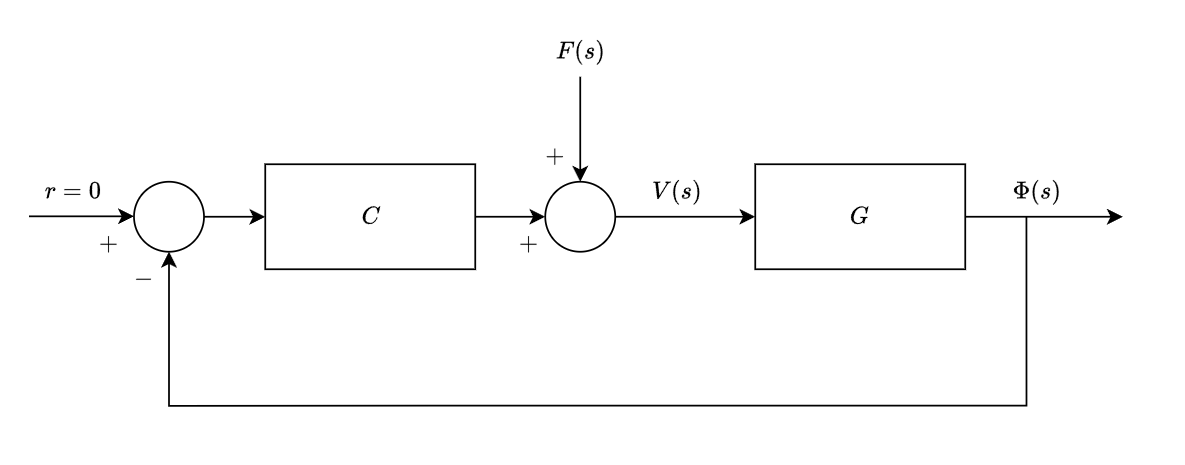

Equivalently:

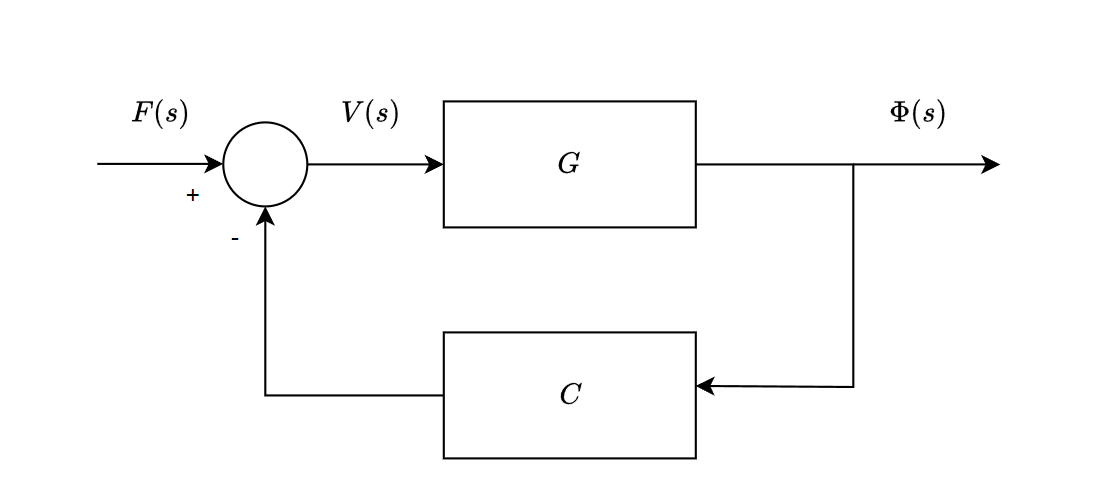

In both representations, the transfer function from $F$ to $\phi$ is given by $\frac{G}{1+GC}$.

Looking at the second representation, we can use feedback(G,C) to get this transfer function.

### Define the plant G

poles_list = [13.58 -7240 -15.97 -2.627];
K_G = 2.206*10^5;

G = zpk(0, poles_list, K_G)

G =
 
                2.206e05 s
  --------------------------------------
  (s-13.58) (s+15.97) (s+2.627) (s+7240)
 
Continuous-time zero/pole/gain model.
Model Properties


### PID controller

tau_p = 1/200;
K_p = 20;
K_i = 20;
K_d = 0.8;
C = tf([K_d K_p K_i], [tau_p 1 0]);

### Print out the 3 dominant poles of the closed loop system

poles_list = pole(feedback(G,C));
dominant_poles = poles_list(4:end)

dominant_poles =  -14.8371 -15.1704i
   0.0000 + 0.0000i
  -0.1009 + 0.0000i


### Root locus of GC

% figure(2); clf; hold on
% rlocus(G*C)
% 
% % restrict axes to focus on the 3 dominant poles
% xlim([1.2*min(real(dominant_poles)), 14])
% ylim([-1.2*max(abs(imag(dominant_poles))), 1.2*max(abs(imag(dominant_poles)))])

### Discretize G and C

Ts = 1/100;
opts = c2dOptions('Method', 'zoh');

C_d = c2d(tf(C), Ts, opts);
num_C_d = C_d.Numerator{1};
den_C_d = C_d.Denominator{1};

G_d = c2d(tf(G), Ts, opts);
num_G_d = G_d.Numerator{1};
den_G_d = G_d.Denominator{1};

### Compare cts and discrete controllers' impulse response

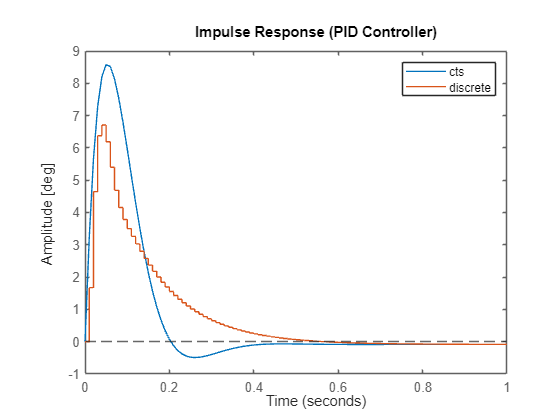

figure(3); clf; hold on

tspan = 0:Ts:1;
impulse_mag = 0.2;
impulse(impulse_mag * feedback(G,C) * 180/pi, tspan)
impulse(impulse_mag * feedback(G_d,C_d) * 180/pi, tspan)

ylabel("Amplitude [deg]")
title("Impulse Response (PID Controller)")
yline(0,'--')
legend('cts','discrete')

### Check saturation is acceptable

The transfer function $\frac{V}{F}$ is given by $\frac{1}{1+GC}$

Max motor voltage is 15V

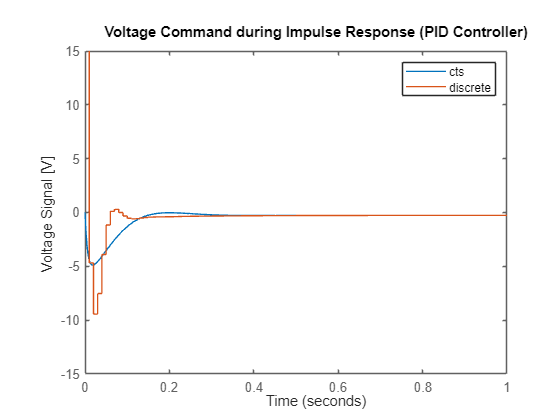

figure(4); clf; hold on
impulse(impulse_mag * 1/(G*C+1))
impulse(impulse_mag * 1/(G_d*C_d+1))
ylim([-15 15])
xlim([0 tspan(end)])
ylabel("Voltage Signal [V]")
title("Voltage Command during Impulse Response (PID Controller)")
legend('cts','discrete')